**Fake News Data: ()**

**Assumptions: **

- **Removed the rows that didn't have a label associated with it.**

- **Used only the text to develop the classifier**

**Resources: MATLAB 2017b (Neural Network Toolbox and Parallel Computing Toolbox), NVIDIA K-40 GPU (for training)**

**Initial set up**

clear

% Set the parameters below as true if you want to train the model. 
doTrain = true; 
doTest = true;

**Loading the Dataset**

% filename = "fake_or_real_news.xlsx";
% data = readtable(filename,'TextType','string');
% save('fakeNewsData.mat')
  load('fakeNewsData.mat');


**Consider the rows where the dataset is labeled as FAKE or REAL.**

**Remove the rows where the text is blank**

idxLabel = find(data.label ~= 'FAKE' & data.label ~= 'REAL');
data(idxLabel,:) = [];

idxEmpty = strlength(data.text) == 0;
data(idxEmpty,:) = [];

data.label = categorical(data.label);

## visualizing the distribution of the classes. There appears to be non class imbalance 

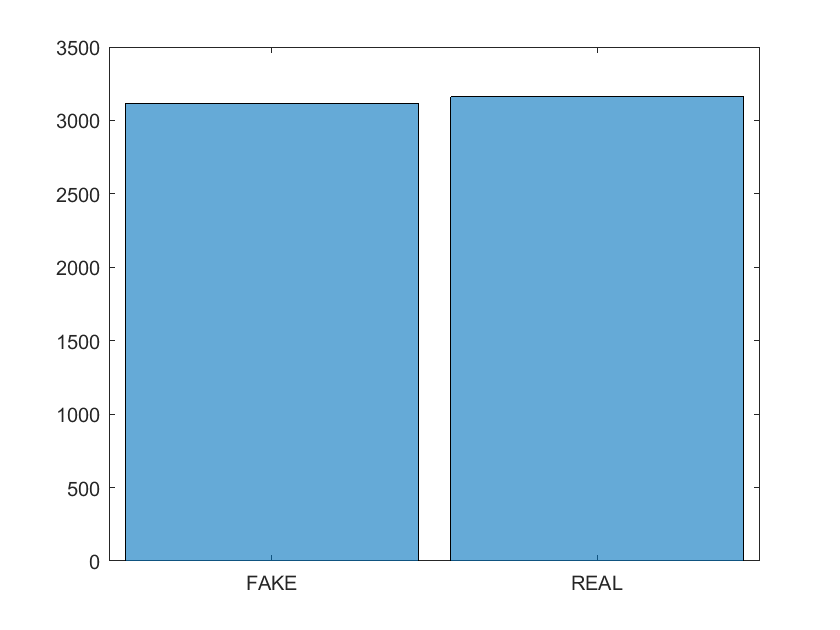

h = histogram(data.label);

## Partitioning the dataset

cvp = cvpartition(data.label,'Holdout',0.1);
dataTrain = data(training(cvp),:);
dataTest = data(test(cvp),:);

## Partitioning into training and test sets

textDataTrain = dataTrain.text;
textDataTest = dataTest.text;
YTrain = dataTrain.label;
YTest = dataTest.label;

## visualize training data using a word cloud

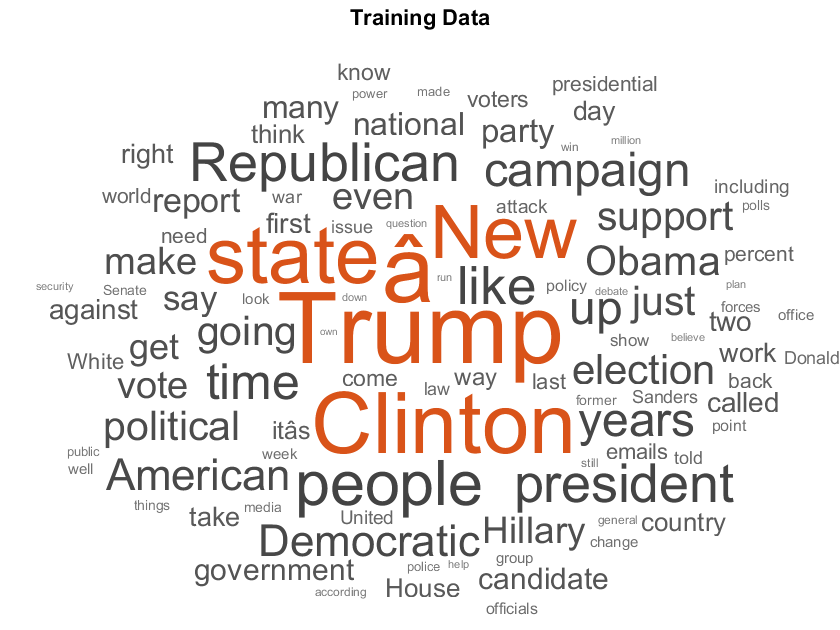

figure
wordcloud(textDataTrain);
title("Training Data")

## Little Preprocessing

textDataTrain = erasePunctuation(textDataTrain);
textDataTrain = lower(textDataTrain);
documentsTrain = tokenizedDocument(textDataTrain);

## Word Embedding 

tic;
embeddingDimension = 100;
embeddingEpochs = 50;

if doTrain
    emb = trainWordEmbedding(documentsTrain, ...
        'Dimension',embeddingDimension, ...
        'NumEpochs',embeddingEpochs, ...
        'Verbose',1)
else
    load('emb.mat');
end

Training: 100% Loss: 1.64922  Remaining time: 0 hours 0 minutes.


emb =   wordEmbedding with properties:

     Dimension: 100
    Vocabulary: [1×28987 string]



toc

Elapsed time is 732.518802 seconds.


## length of docs

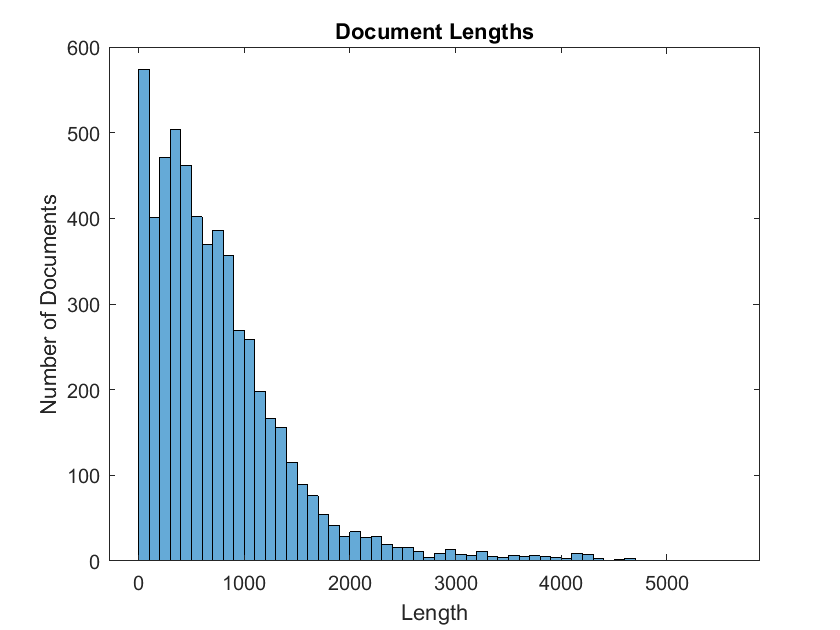

documentLengths = doclength(documentsTrain);
figure
histogram(documentLengths)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")

## Since most of the docs have tokens of size 1200, padding with seq length of 1200

sequenceLength = 1200;
documentsTruncatedTrain = docfun(@(words) words(1:min(sequenceLength,end)),documentsTrain);
save('emb_1200')

## Converting the doc to sequences to be fed into the LSTM

XTrain = doc2sequence(emb,documentsTruncatedTrain);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 12 workers.


## Left Padding

for i = 1:numel(XTrain)
    XTrain{i} = leftPad(XTrain{i},sequenceLength);
end
XTrain(1:5)';

## Train Network

inputSize = embeddingDimension;
outputSize = 100;
numClasses = numel(categories(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(outputSize,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 100 dimensions
     2   ''   LSTM                    LSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

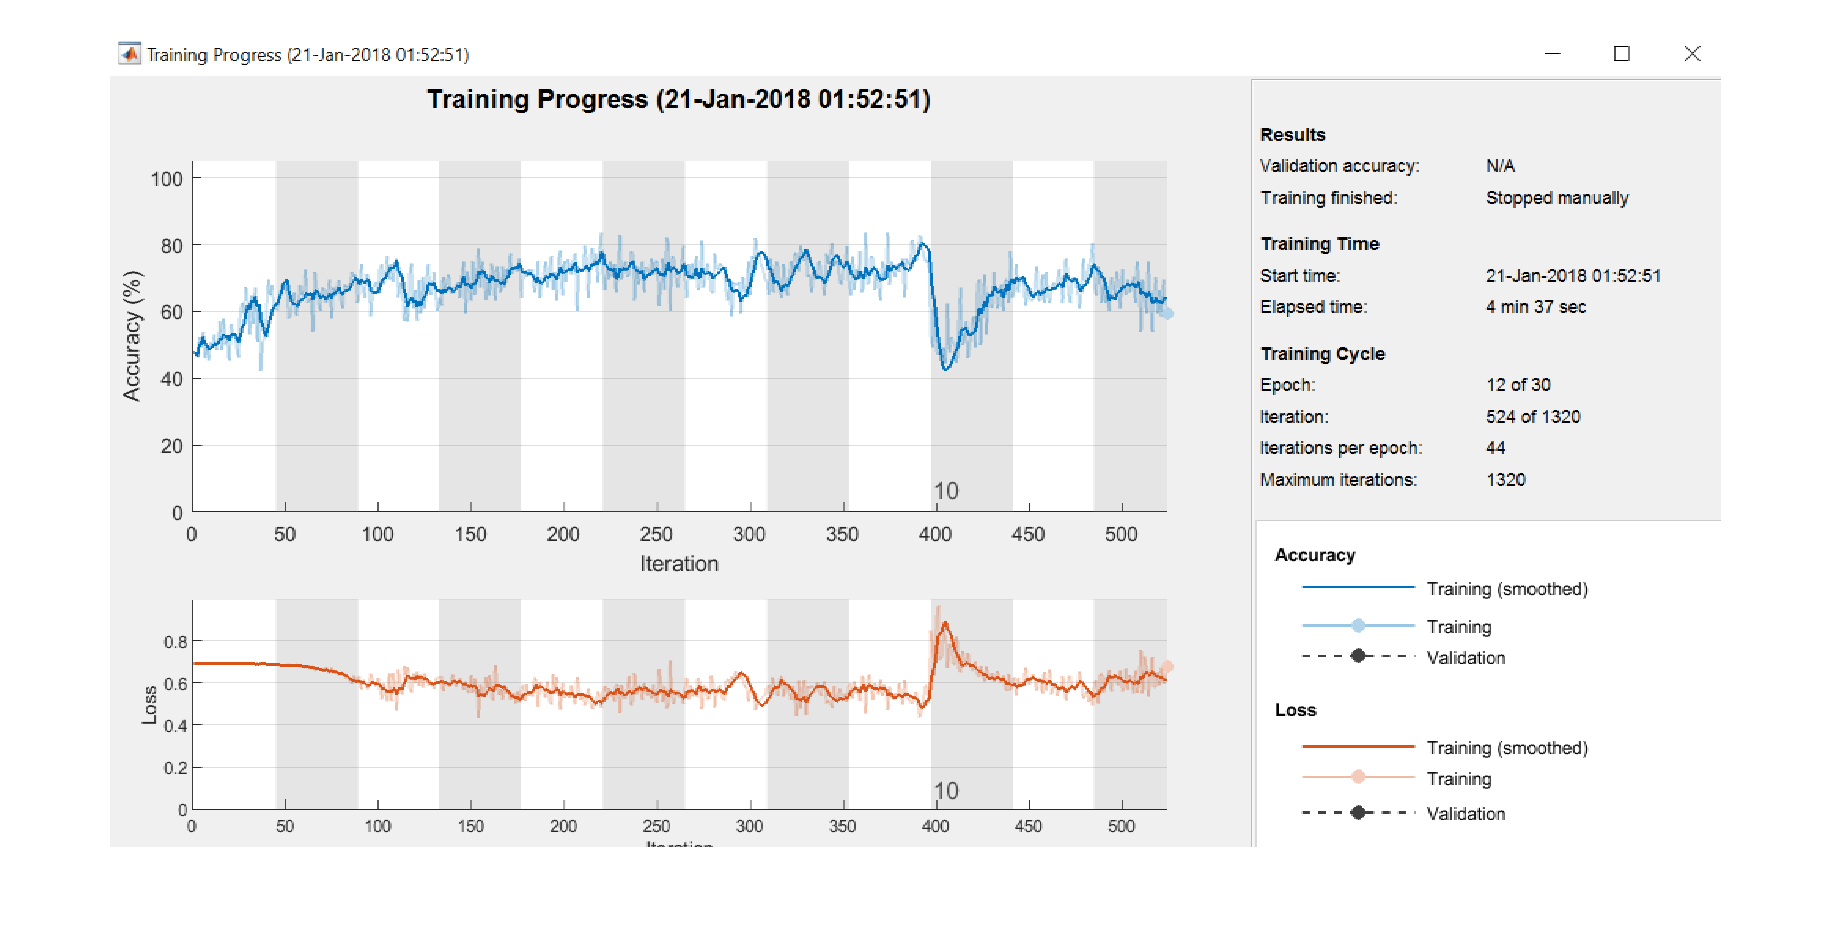

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...    
    'Plots','training-progress', ...
    'Verbose',1)

**Train Network (training with default options)**

if doTrain
    net = trainNetwork(XTrain,YTrain,layers,options);
    save('firstPassNetwork.mat')
else
    load('lstmFake_firstPass.mat');
    imshow('firstPassNetwork.PNG');
end

options =   TrainingOptionsSGDM with properties:

                     Momentum: 0.9000
             InitialLearnRate: 0.0500
    LearnRateScheduleSettings: [1×1 struct]
             L2Regularization: 1.0000e-04
      GradientThresholdMethod: 'l2norm'
            GradientThreshold: Inf
                    MaxEpochs: 30
                MiniBatchSize: 128
                      Verbose: 1
             VerboseFrequency: 50
               ValidationData: []
          ValidationFrequency: 50
           ValidationPatience: 5
                      Shuffle: 'never'
               CheckpointPath: ''
         ExecutionEnvironment: 'auto'
                   WorkerLoad: []
                    OutputFcn: []
                        Plots: 'training-progress'
               SequenceLength: 'longest'
         SequencePaddingValue: 0


**Runnning the network on default hyperparameters yielded low accuracy with drops in training progress. This suggests that the Initial learning rate be adjusted, and possibly, reduced after every nth epoch so that the objective func reaches a global minima and not diverge. Hence, adding a drop factor of 0.2 after every 2 epochs so that the steps for the learning rate become smaller with time**

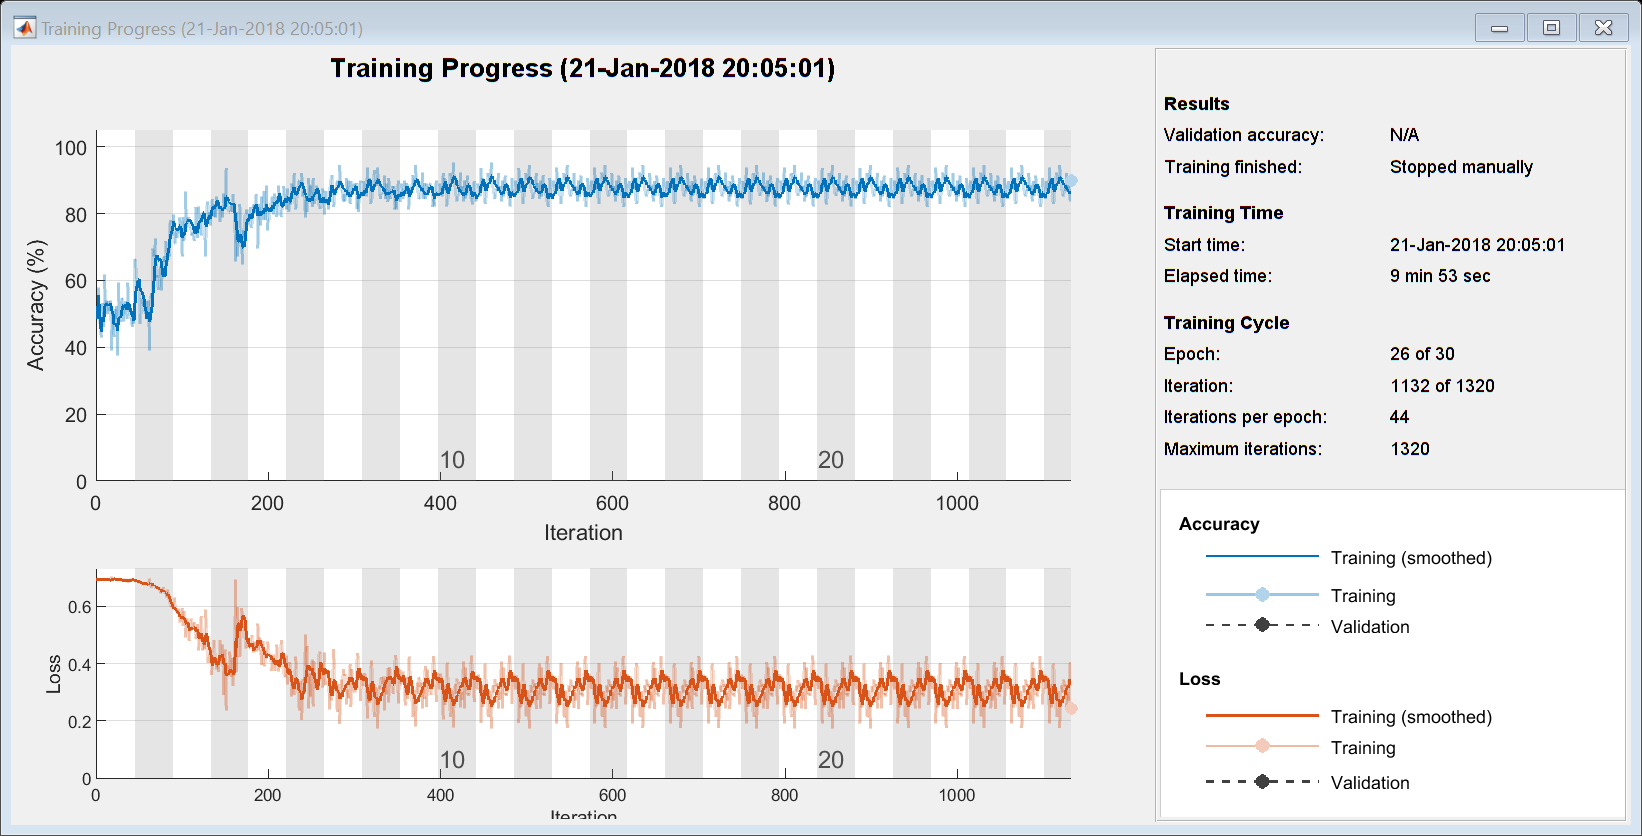

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       52.34% |       0.6931 |          0.0500 |
|       2 |          50 |       00:00:26 |       57.03% |       0.6825 |          0.0500 |
|       3 |         100 |       00:00:52 |       67.19% |       0.5932 |          0.0100 |
|       4 |         150 |       00:01:18 |       82.81% |       0.4485 |          0.0100 |
|       5 |         200 |       00:01:44 |       78.13% |       0.4621 |          0.0020 |
|       6 |         250 |       00:02:11 |       85.16% |       0.3944 |          0.0020 |
|       7 |         300 |       00:02:38 |       89.06% |       0.

options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise',...
    'InitialLearnRate',0.05, ...    
    'LearnRateDropFactor',0.2,...
    'LearnRateDropPeriod',2,...
    'Shuffle','never',...
    'Plots','training-progress', ...

    'Verbose',1)

if doTrain
    net = trainNetwork(XTrain,YTrain,layers,options);
    save('thirdPassNetwork.mat')
else
    load('lstmFake_secondPass_88.mat');
    imshow(('secondPassNetwork.PNG'));
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 12 workers.


## testing

textDataTest = erasePunctuation(textDataTest);
textDataTest = lower(textDataTest);
documentsTest = tokenizedDocument(textDataTest);

## Convert the docs to seq

documentsTruncatedTest = docfun(@(words) words(1:min(sequenceLength,end)),documentsTest);

ans = 1×5 cell array
    {100×1200 single}    {100×1200 single}    {100×1200 single}    {100×1200 single}    {100×1200 single}


XTest = doc2sequence(emb,documentsTruncatedTest);
for i=1:numel(XTest)
    XTest{i} = leftPad(XTest{i},sequenceLength);
end
XTest(1:5)

## Inference

YPred = classify(net,XTest);

accuracy = 0.8947

## accuracy

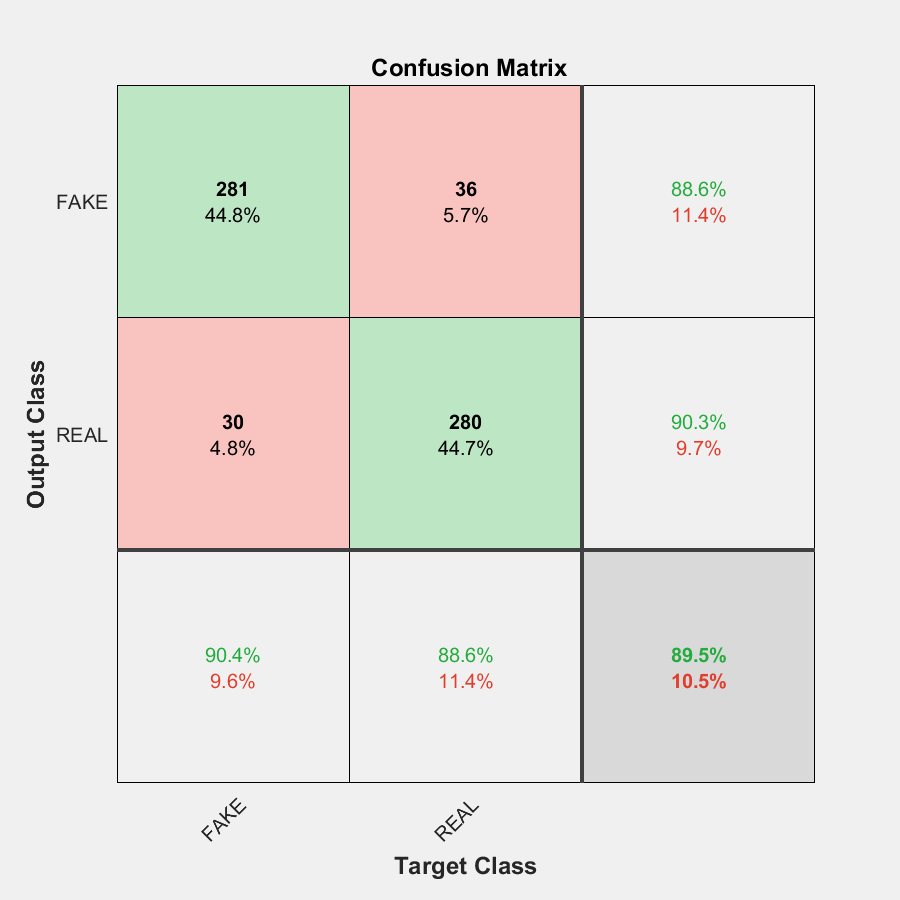

accuracy = sum(YPred == YTest)/numel(YPred)

Plot confusion

plotconfusion(YTest,YPred);